# Dimensional Analysis and Vector Calculus

AA 507 Winter 2026, UW

Assignment: Homework 1 

(Ref file: HW1_2026.pdf)

Author: Emmanuel Rodriguez

[emmanueljrodriguez.com](https://emmanueljrodriguez.com/)

Date: 20JAN2026

 - 23JAN2026

Location: Renton, Seattle, WA

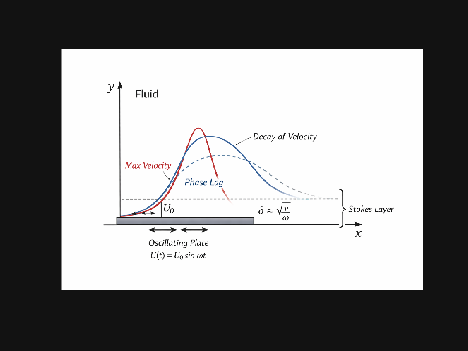

clear all;

## Problem 1. Dimensional analysis: oscillating Stokes layer

[Continue here... -ERODRIGUEZ2, 20JAN2026 21:40]

### Background

The Stokes oscillating layer (or oscillatory boundary layer) describes the thin layer of viscous fluid near a surface that moves back and forth due to oscillatory motion, such as a large flat plate oscillating siunusoidally in its own plane with a given velocity, $U(t)$. Ref figure.

Where $U(t) = U_0cos(\omega t)$

imshow("Stokes oscillatory boundary layer diagram.21JAN2026.png")

**Exponential Decay:** The fluid velocity oscillates with the same frequency as the wall, but its amplitude decays exponentially as distance from the wall increases. [1]

### Applications

#### Heat Transfer Enhancement

Compact heat exchangers need effective mixing, which occurs when the oscillation frequency is tuned so $\delta$ matches the thermal diffusion length. [2]

#### Vibration-Induced Drag & Noise

Used in early-stage aeroelastic modeling to estimate viscous energy losses. The Stokes layer determines aerodynamic damping, noise generation, and flutter stability. [3]

### Analysis

Assumptions:

- Flow is laminar and two dimensional

- Compressibility and gravity is neglected

The characteristic thickness $\delta$ of the oscillatory boundary layer is the distance from the wall where the velocity amplitude has decayed to 1/*e* of its wall value.

#### 1. Dimensional analysis for $\delta$

Using the Buckingham- $\prod$ theorem --

Step 1

List parameter in functional form:


$$\delta = f(\omega, \rho, \mu)$$


this functional relationship posits the idea that the boundary layer thickness (dependent variable) is a function of independent variables: angular frequency, and the fluid's density and viscosity.

$n = 4$ (four total parameters)

Step 2

**Primary dimensions**

- 
$$\delta: [L^1]$$


- 
$$\omega: [T^-1]$$


- 
$$\rho: [M^{1}L^{-3}]$$


- 
$$\mu: [M^1L^{-1}T^{-1}]$$


$\rightarrow$ 3 primary dimensions

Step 3

Set the reduction *j *as the number of primary dimensions (initial guess)

Reduction: $j = 3$

If correct, number of $\prod$'s: $k = n - j = 4 - 3 = 1$

Step 4

Choose *j *repeating parameters.

Repeating parameters: $\omega, \rho, \mu$

- Note: Following the guidelines for picking repeating parameters, we cannot pick the dependent variable $\delta$

Step 5

Construct *k* $\Pi$'s, manipulate as necessary.

The dependent $\Pi_1$ is generated by assuming a dimensionless product:


$$\Pi_{1} = \delta \omega^a \rho^b \mu^c$$


Force $\Pi_1$ to be dimensionless by setting the exponent of each primary dimension to zero. Then determine the constant exponents by equating the exponents of each primary dimension:

%% Buckingham Pi via Symbolic Math Toolbox
% Variables: delta, omega, rho, mu
% Dimensions (M, L, T):
%   delta : L^1
%   omega : T^-1
%   rho   : M^1 L^-3
%   mu    : M^1 L^-1 T^-1

clear; clc;

syms a b c real           % unknown exponents for omega, rho, mu
syms delta omega rho mu    % symbols for readability (not strictly needed)

% Dimension exponents for each variable in [M L T] order
% Rows correspond to variables: [delta; omega; rho; mu]
D = [ 0  1  0;   % delta
      0  0 -1;   % omega
      1 -3  0;   % rho
      1 -1 -1];  % mu

% Build the dimension balance for Pi = delta^1 * omega^a * rho^b * mu^c
% Total exponents in [M L T] must be zero:
%   1*D(delta,:) + a*D(omega,:) + b*D(rho,:) + c*D(mu,:) = [0 0 0]
eqM = D(1,1) + a*D(2,1) + b*D(3,1) + c*D(4,1) == 0;
eqL = D(1,2) + a*D(2,2) + b*D(3,2) + c*D(4,2) == 0;

Solved exponents:


eqT = D(1,3) + a*D(2,3) + b*D(3,3) + c*D(4,3) == 0;

a = 1/2


b = 1/2


sol = solve([eqM, eqL, eqT], [a, b, c], 'ReturnConditions', true);

c = -1/2



a_sol = simplify(sol.a);
b_sol = simplify(sol.b);
c_sol = simplify(sol.c);

Buckingham-Pi group Pi =


delta sqrt(omega) sqrt(rho)
---------------------------
          sqrt(mu)



fprintf('Solved exponents:\n');
fprintf('a = %s\n', string(a_sol));
fprintf('b = %s\n', string(b_sol));
fprintf('c = %s\n', string(c_sol));

Equivalent simplified form:


          / omega rho \
delta sqrt| --------- |
          \     mu    /



% Construct the Pi group
Pi = simplify(delta * omega^a_sol * rho^b_sol * mu^c_sol);
disp('Buckingham-Pi group Pi =');
pretty(Pi)

% Optional: express Pi in a nicer combined form
Pi_nice = simplify(delta * sqrt(omega*rho/mu));
disp('Equivalent simplified form:');
pretty(Pi_nice)

(a) Thus, the only minimal independent group is:


$$\Pi_1 = \delta \left( \frac{\omega \rho}{\mu} \right)^{1/2}$$


(b) Re-writing the result in the form:


$$\frac{\delta}{\L_{*}} = \Phi(\Pi)$$


%% Dimensional analysis – Part (2)
% Writing the result as delta / L* = Phi(Pi)

clear; clc;

syms delta omega nu real positive

% Define characteristic length scale
Lstar = sqrt(nu/omega);

% Define the Buckingham Pi group

Characteristic length scale L* =


Pi = simplify(delta / Lstar);

  sqrt(nu)
-----------
sqrt(omega)




disp('Characteristic length scale L* =');

Buckingham Pi group Pi = delta / L* =


pretty(Lstar)

delta sqrt(omega)
-----------------
     sqrt(nu)




disp('Buckingham Pi group Pi = delta / L* =');
pretty(Pi)

% Express the dimensional-analysis result symbolically
Phi = sym('C');   % unknown O(1) constant from dimensional analysis

Final dimensional-analysis result:


delta_result = simplify(Phi * Lstar);

delta = Phi * L* =


 C sqrt(nu)
-----------
sqrt(omega)



disp('Final dimensional-analysis result:');
disp('delta = Phi * L* =');
pretty(delta_result)

This is what the code is communicating mathematically:

- Characteristic length scale: $L^* = \sqrt{\frac{\nu}{\omega}}$

- **Single **$\Pi$**-group:** $\Pi = \frac{\delta}{L^*} = \delta \sqrt{\frac{\omega}{\nu}}$

- Since there is only one $\Pi$-group, the functional relation reduces to a constant: $\frac{\delta}{L^*} = \Phi = C$

- Therefore, the Stokes layer thickness scales as: $\delta = C \sqrt{\frac{\nu}{\omega}}$

#### 2. Identify the controlling parameter

[Note: When the problem asks for the controlling parameter, it is asking:

- Which dimensionless combination of variables governs the physics of the problem -- i.e., determines the regime and behavior of the flow?]

Let $\nu = \mu / \rho$ be the kinematic viscosity.

Equivalently,


$$\delta = C \sqrt{\frac{\nu}{\omega}}$$


Rewriting the $\Pi$-group to:

$\Pi^2 = \frac{\omega \delta^2}{\nu}$ $\leftarrow$ **is the controlling parameter.**

**One sentence interpretation of what the parameter compares:**

$\omega \delta^2 / \nu$ compares the oscillation timescale $(1/\omega)$ to the viscous diffusion timescale across the oscillatory boundary layer $\delta (\delta^2 / \nu)$ - i.e., how far momentum can diffuse in one cycle.

#### Bonus

If we retain the plate velocity, then our oscillating boundary layer becomes:


$$\delta = f(U_0, \omega, \rho, \mu)$$


- Using the same characteristic length: $L^* = \sqrt{(\nu / \omega)}$ (the viscous penetration depth per oscillation)

$\Pi$**-group 1: nondimensional thickness**

$\Pi_1 = \frac{\delta}{\sqrt{\nu/\omega}}$ $\leftarrow$ This measures how thick the layer is compared to the viscous diffusion length.

$\Pi$**-group 2: nondimensional velocity amplitude**

We nondimensionalize $U_0$ using the velocity scale associated with $L^*$:


$$U^* \sim \frac{L^*}{T_{osc}} = \sqrt{\nu \omega}$$


So:

$\Pi_2 = \frac{U_0}{\sqrt{\nu \omega}}$ $\leftarrow$ This is essentially a **Reynolds number** based on the Stokes layer thickness; it measures the oscillation strength.

- Large $\Pi_2$ indicates possible flow seperation, streaming, turbulence.

**Buckingham-**$\Pi$** form:**


$$\frac{\delta}{\sqrt{\nu/\omega}} = \Phi \left( \frac{U_0}{\sqrt{\nu \omega}} \right)$$


The velocity amplitude now controls whether the Stokes solution is valid.

## References

[1] [https://en.wikipedia.org/wiki/Stokes_problem](https://en.wikipedia.org/wiki/Stokes_problem)

[2] **S. T. Raml, *****Oscillatory Flow Mechanism for Enhanced Heat Transfer*** — Master’s thesis demonstrating how oscillating boundary motion can improve convective heat transfer by inducing unsteady boundary–layer motion. 

[3] **Stokes Problem overview (classic fluid dynamics text references)** — Standard fluid mechanics sources (e.g., Batchelor, *An Introduction to Fluid Dynamics*, and Landau & Lifshitz, *Fluid Mechanics*) establish the fundamental oscillatory boundary layer solutions from which damping and drag models are derived.